# Heat transfer example

The heat transfer in a 1D semi-infinite homogeneous solid can be modelled with the following equation: 


$$\[ 
\frac{\partial T}{\partial t}-\nabla.(\alpha \nabla T) = 0 
\]$$


with the boundary condition

$T=T_s$ at $x=0$, $t>0$

The solution of this equation reads


$$T(x,t)=(T_0-T_s )  erf (x/\sqrt{4\alpha t})+T_s$$


and for a constant flux boundary condition, it reads


$$T(x,t)=T_0+\frac{q_s}{k} \sqrt \frac{4 \alpha t}{\pi}  \exp (-x^2/4\alpha t)-q_s/k x(1- erf (x/\sqrt{4\alpha t})$$


For an initial condition of 

$T = T_0$ at $t=0$

In th above equations, $\alpha = \frac{k}{\rho c}$ [m^2/s] denotes the heat diffusivity and is calculated by dividing the heat conductivity by the heat capacity per unit volume. We cannot have a semi-inifinite domain in the numerical method. Therefore, we have to define the simulation time such that the heat flux does not reach the end of the domain. Heat diffusivity can guide us here (with the arbitrarily chosen factor 10, and $L$ the length of the domain):


$$t < \frac{L^2}{10 \alpha}$$


## Physical parameters

% Parameters
L = 1.0; % [m] domain length
k = 20.0; % 0.6 for water, 0.025 for air W/m/K
rho = 8000.0; % kg/m^3
c = 500.0; % J/kg/K (4200 for water, 1000 for air)
alfa = k/(rho*c); % heat diffusion
T0 = 300.0; % [K]
Ts = 350.0; % [K]
qs = 1000; % [W/m^2]
t_sim = L^2/(20*alfa); % [s]
time_steps = 50;
dt = t_sim/time_steps; % 

The funny thing about heat capacity is that the value per unit volume is almost the same for different metals (and water).

## Numerical model

First, we define the domain

Nx = 20; % number of cells
m = createMesh1D(Nx, L);

Then, we define the boundary condition. We have two choices:

left_bc = "Neumann";
% Boundary condition
BC = createBC(m);
if strcmpi(left_bc, "Dirichlet")
    BC.left.a(:) = 0.0;
    BC.left.b(:) = 1.0;
    BC.left.c(:) = Ts;
    T_analytic = @(x,t)T_analytical_dirichlet(x, t, alfa, T0, Ts);
else
    BC.left.a(:) = k;
    BC.left.b(:) = 0.0;
    BC.left.c(:) = -qs;
    T_analytic = @(x,t)T_analytical_neuman(x, t, alfa, T0, k, qs);
end

Now, we define the initial condition:

% Initial condition
T_init = createCellVariable(m, T0, BC); % initial condition
% physical parameters
alfa_cell = createCellVariable(m, alfa);
alfa_face = harmonicMean(alfa_cell);

The matrices of coefficients for the diffusion and BC terms are calculated by:

M_diff = diffusionTerm(alfa_face);
[M_bc, RHS_bc] = boundaryCondition(BC);

and finally we create the time loop:

for t = dt:dt:t_sim
    [M_trans, RHS_trans] = transientTerm(T_init, dt);
    T_val = solvePDE(m, M_bc+M_trans-M_diff, RHS_bc+RHS_trans);
    T_init = T_val;
end

Finally, we plot the numerical and analytical solutions:

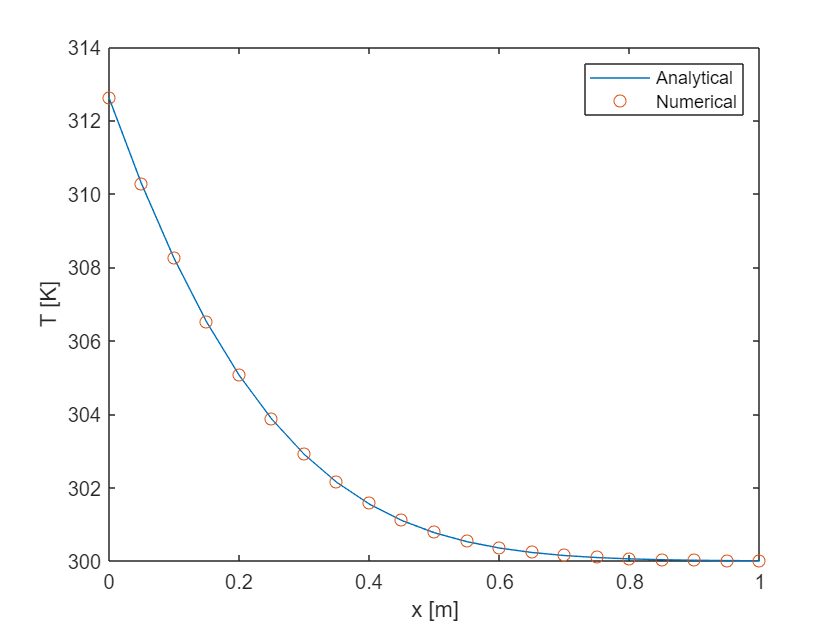

x = m.facecenters.x;
T_face = linearMean(T_val);
T_num = T_face.xvalue;
plot(x, T_analytic(x, t_sim), x, T_num, 'o');
legend({'Analytical', 'Numerical'});
xlabel('x [m]');
ylabel('T [K]');